# Cascaded LTI system

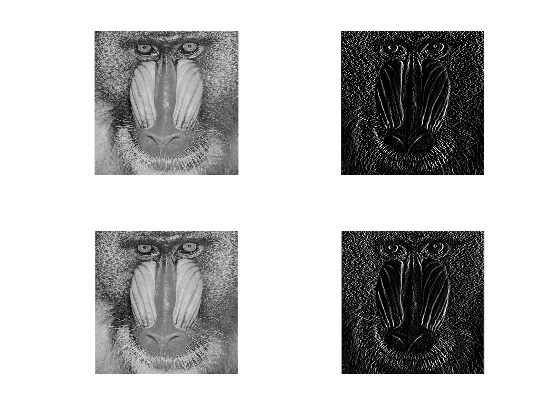

h1=ones(3,3)/9;   % average filter
h2=[1 1 1, 0 0 0, -1 -1 -1];    %1st different in horizontal line
x=imread('monkey.jpg');
v=imfilter(x,h1);    % the 1st output from low-pass
y1=imfilter(v,h2);  % 2nd output from  high-pass
% end of first filter order
 
w=imfilter(x,h2);    % the 1st output from high-pass
y2=imfilter(w,h1);  % 2nd output from  low-pass
% end of second filter order
 
subplot(2,2,1); imshow(x);
subplot(2,2,2); imshow(y1);
subplot(2,2,3); imshow(x);
subplot(2,2,4); imshow(y2);

## Low Pass Filter (Sound)

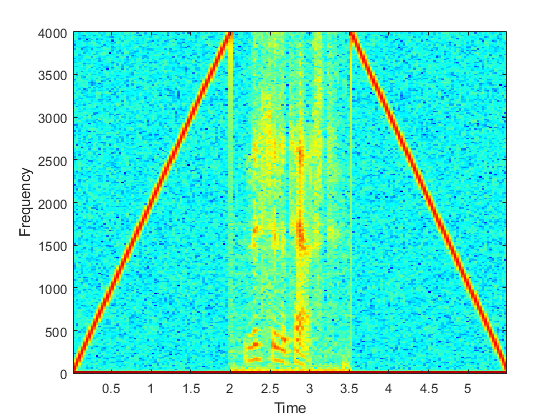

[x fs]=audioread('thisin.wav');
sound(x,fs)
figure;
specgram(x,512,fs);

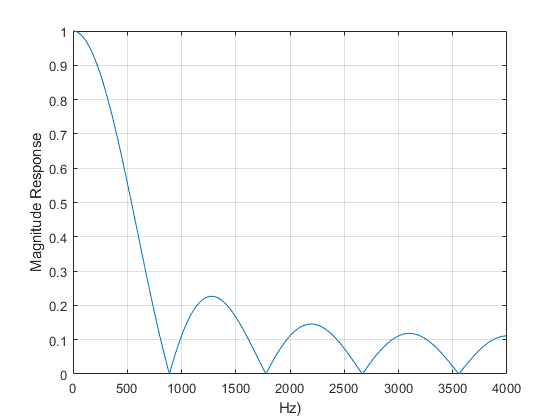

a=[1];
b=[1 1 1 1 1 1 1 1 1]/9;
[H f]= freqz(b,a,512,fs);
figure;
plot(f,abs(H))
grid on; 
ylabel('Magnitude Response')
xlabel('Hz)')

y=filter(b,a,x);
sound(y,fs)

figure;
specgram(x,512,fs);